**ΤΕΧΝΟΛΟΓΙΑ ΉΧΟΥ **

**Εργασία 3**

**Παναγιώτα Μωραΐτη** 

1. Προσθετική Σύνθεση

Υλοποίηση της add_synth.m.

2. Αφαιρετική Σύνθεση

Υλοποίηση της sub_synth.m.

3. Σύνθεση FM

Υλοποίηση της fm_synth.m.

4. Υλοποίηση Μουσικού Κομματιού

fs = 16000;
T = 0.5;
song = moon(fs, T);
player = audioplayer(song, fs); 
play(player);

a) Χρησιμοποιήσαμε την add_synth για να υλοποιήσουμε το μουσικό κομμάτι σε διαφορετικά προφίλ μουσικών οργάνων.

% Piano
fs = 44100;
T = 0.5;
profile_name1 = 'piano_profile.mat';
song1 = profile_add(profile_name1, T, fs);
soundsc(song1, fs);

% Clarinet
fs = 44100;
T = 0.5;
profile_name2 = 'clarinet_profile.mat';
song2 = profile_add(profile_name2, T, fs);
soundsc(song2, fs);

% Flute
fs = 44100;
T = 0.5;
profile_name3 = 'flute_profile.mat';
song3 = profile_add(profile_name3, T, fs);
soundsc(song3, fs);

Παρακάτω βλέπουμε τα φασματογραφήματα των παραχθέντων ήχων.

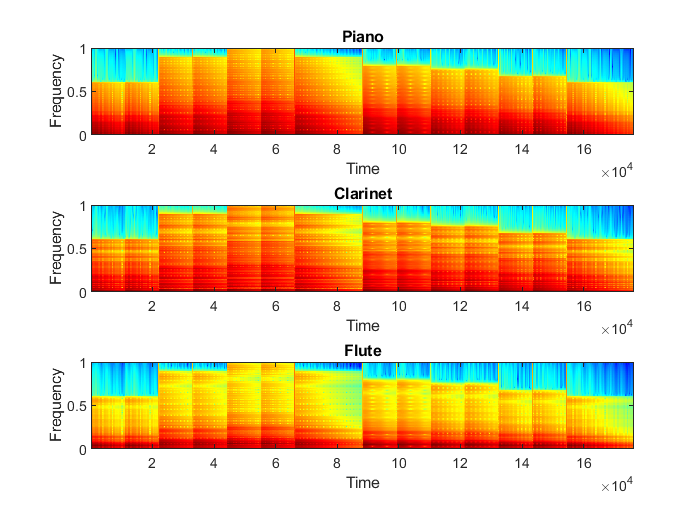

subplot(3,1,1)
specgram(song1);
title('Piano');
subplot(3,1,2)
specgram(song2);
title('Clarinet');
subplot(3,1,3)
specgram(song3);
title('Flute');

Το φασματογράφημα απεικονίζει το φράσμα του σήματος, δηλαδή το σύνολο των συχνοτήτων που το απαρτίζουν ως συνάρτηση του χρόνου. Στον οριζόντιο άξονα εξελίσσεται ο χρόνος, ενώ στον κατακόρυφο η συχνότητα. Με κόκκινο χρώμα χρωματίζονται οι περιοχές μεγάλου πλάτους και με μπλε οι περιοχές μικρού πλάτους. 

Όσο πιο έντονα χρώματα έχουμε, τόσο μεγαλύτερη είναι η ένταση των συγκεκριμένων συχνοτήτων (πχ. μπλε-πράσινο-κίτρινο-πορτοκαλί-κόκκινο, όσο πιο δεξιά βρίσκεται το χρώμα σε αυτήν την κλίμακα, τόσο μεγαλύτερη η ένταση της συγκεκριμένης συχνότητας). Το μπλε σημαίνει ότι δεν έχουμε μεγάλη ένταση σε μια συγκεκριμένη συχνότητα, ενώ το κόκκινο ότι η ένταση είναι πολύ μεγάλη.

Παρατηρούμε ότι τα φασματογραφήματα του πιάνου και του κλαρινέτου μοιάζουν αρκετά μεταξύ τους, ενώ του φλάουτου είναι πιο κίτρινο από τη μέση και πάνω (με εξαίρεση τις πολύ χαμηλές συχνότητες στη βάση του γραφήματος). Αυτο οφείλεται στο γεγονός ότι οι δύο πρώτοι ήχοι ακούγονται σχετικά παρόμοιοι (παρόμοιες συχνότητες), ενώ στο φλάουτο η ένταση των χαμηλών συχνοτήτων είναι μεγαλύτερη (η ένταση των υψηλών συχνοτήτων είναι μικρότερη -> κίτρινο, πράσινο, οι χαμηλές είναι εντονότερες και κυριαρχούν -> πορτοκαλί, κόκκινο).

b) Χρησιμοποιήσαμε την sub_synth για να υλοποιήσουμε το μουσικό κομμάτι σε διαφορετικά προφίλ.

% A profile
fs = 44100;
T = 0.5;
osc_type1 = "rect";
osc_type2 = "sawtooth";
fc1 = 500;
fc2 = 700;
song4 = profile_sub(T, fs, osc_type1, fc1, osc_type2, fc2);
soundsc(song4, fs);

% B profile
osc_type1 = "sawtooth";
osc_type2 = "triangle";
fc1 = 1300;
fc2 = 900;
song5 = profile_sub(T, fs, osc_type1, fc1, osc_type2, fc2);
soundsc(song5, fs);

% Γ profile
osc_type1 = "rect";
osc_type2 = "triangle";
fc1 = 400;
fc2 = 1000;
song6 = profile_sub(T, fs, osc_type1, fc1, osc_type2, fc2);
soundsc(song6, fs);

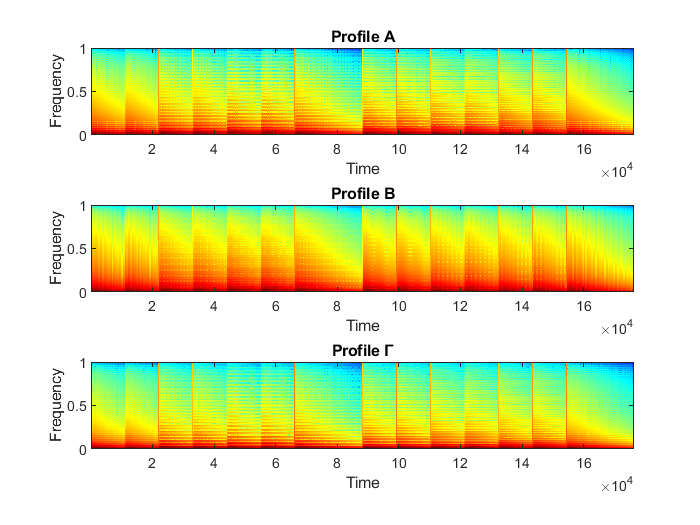

subplot(3,1,1)
specgram(song4);
title('Profile A');
subplot(3,1,2)
specgram(song5);
title('Profile B');
subplot(3,1,3)
specgram(song6);
title('Profile Γ');

Παρατηρούμε ότι τα φασματογραφήματα του Profile Α και του Profile Β μοιάζουν αρκετά μεταξύ τους, ενώ του Profile Γ δεν έχει τόσο πορτοκαλί σε υψηλότερες συχνότητες (εμπεριέχει κυρίως χαμηλότερες συχνότητες σε μεγαλύτερη ένταση). Το Profile Β περιέχει και υψηλότερες συχνότητες σε μεγαλύτερη ένταση σε σχέση με τα άλλα δύο.

c) Χρησιμοποιήσαμε την fm_synth για να υλοποιήσουμε το μουσικό κομμάτι σε διαφορετικά προφίλ.

% Δ profile
fs = 44100;
T = 0.5;
Q=1;
B=5;
song7 = profile_fm(T, fs, Q, B);
soundsc(song7, fs);

% Ε profile
Q=2/3;
B=15;
song8 = profile_fm(T, fs, Q, B);
soundsc(song8, fs);

% ΣΤ profile
Q=7/5;
B=15;
song9 = profile_fm(T, fs, Q, B);
soundsc(song9, fs);

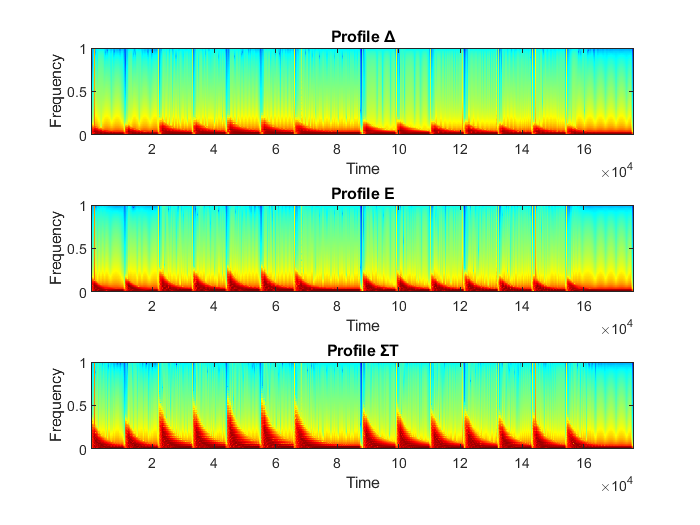

subplot(3,1,1)
specgram(song7);
title('Profile Δ');
subplot(3,1,2)
specgram(song8);
title('Profile Ε');
subplot(3,1,3)
specgram(song9);
title('Profile ΣΤ');

Από το Profile Δ, στο Profile Ε και στο Profile ΣΤ, παρατηρούμε ότι η περιεκτικότητα σε κόκκινο χρώμα αυξάνεται και σχηματίζει τριγωνάκια με κορυφές σε υψηλότερη συχνότητα. Στο Profile ΣΤ έχουμε τα μεγαλύτερα τριγωνάκια, δηλαδή ακούγεται εντονότερα το εφέ. Στο Profile Δ, το εφέ ακούγεται λιγότερο από τα άλλα δύο (μικρότερα τριγωνάκια).

5. Υλοποίηση Εφέ Παραμόρφωσης 

drive1 = 50;
drive2 = 90;
fs = 44100;

%song1
song1_dist1 = dist(song1, drive1);
soundsc(song1_dist1, fs);

song1_dist2 = dist(song1, drive2);
soundsc(song1_dist2, fs);

%song2
song2_dist1 = dist(song2, drive1);
soundsc(song2_dist1, fs);

song2_dist2 = dist(song2, drive2);
soundsc(song2_dist2, fs);

%song3
song3_dist1 = dist(song3, drive1);
soundsc(song3_dist1, fs);

song3_dist2 = dist(song3, drive2);
soundsc(song3_dist2, fs);

%song4
song4_dist1 = dist(song4, drive1);
soundsc(song4_dist1, fs);

song4_dist2 = dist(song4, drive2);
soundsc(song4_dist2, fs);

%song5
song5_dist1 = dist(song5, drive1);
soundsc(song5_dist1, fs);

song5_dist2 = dist(song5, drive2);
soundsc(song5_dist2, fs);

%song6
song6_dist1 = dist(song6, drive1);
soundsc(song6_dist1, fs);

song6_dist2 = dist(song6, drive2);
soundsc(song6_dist2, fs);

%song7
song7_dist1 = dist(song7, drive1);
soundsc(song7_dist1, fs);

song7_dist2 = dist(song7, drive2);
soundsc(song7_dist2, fs);

%song8
song8_dist1 = dist(song8, drive1);
soundsc(song8_dist1, fs);

song8_dist2 = dist(song8, drive2);
soundsc(song8_dist2, fs);

%song9
song9_dist1 = dist(song9, drive1);
soundsc(song9_dist1, fs);

song9_dist2 = dist(song9, drive2);
soundsc(song9_dist2, fs);

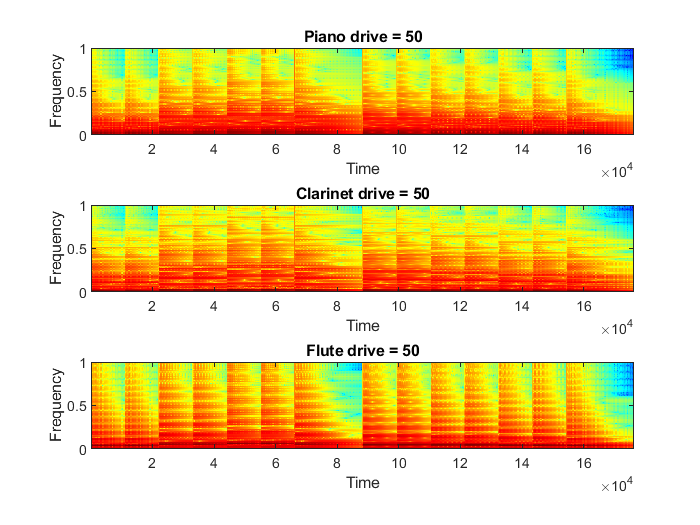

subplot(3,1,1)
specgram(song1_dist1);
title('Piano drive = 50');
subplot(3,1,2)
specgram(song2_dist1);
title('Clarinet drive = 50');
subplot(3,1,3)
specgram(song3_dist1);
title('Flute drive = 50');

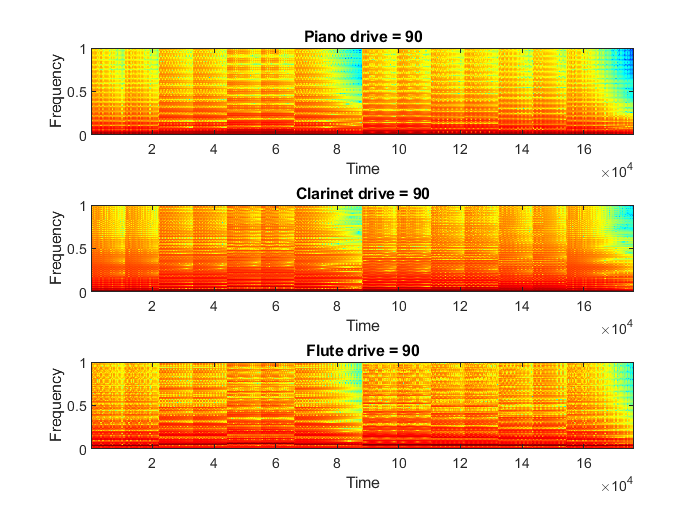

figure
subplot(3,1,1)
specgram(song1_dist2);
title('Piano drive = 90');
subplot(3,1,2)
specgram(song2_dist2);
title('Clarinet drive = 90');
subplot(3,1,3)
specgram(song3_dist2);
title('Flute drive = 90');

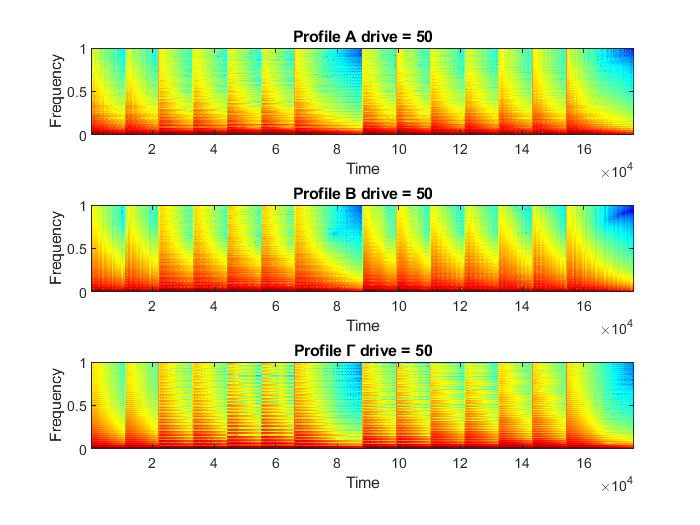

figure
subplot(3,1,1)
specgram(song4_dist1);
title('Profile A drive = 50');
subplot(3,1,2)
specgram(song5_dist1);
title('Profile B drive = 50');
subplot(3,1,3)
specgram(song6_dist1);
title('Profile Γ drive = 50');

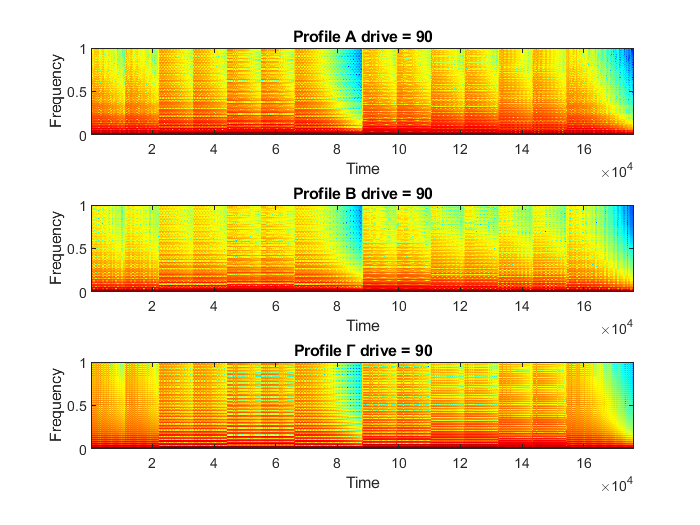

figure
subplot(3,1,1)
specgram(song4_dist2);
title('Profile A drive = 90');
subplot(3,1,2)
specgram(song5_dist2);
title('Profile B drive = 90');
subplot(3,1,3)
specgram(song6_dist2);
title('Profile Γ drive = 90');

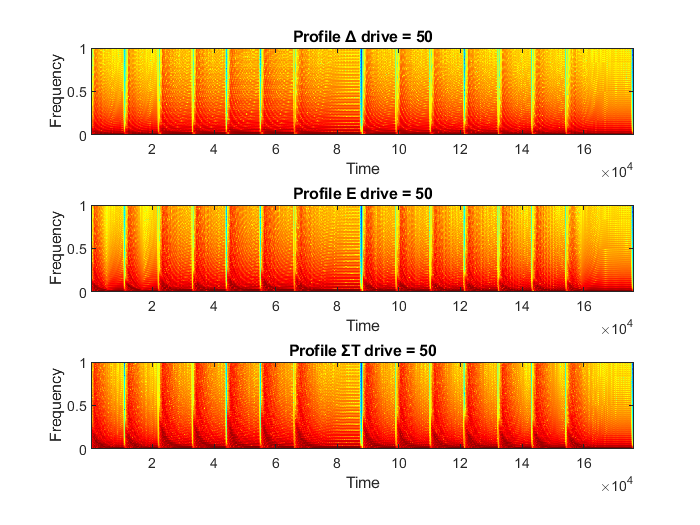

figure
subplot(3,1,1)
specgram(song7_dist1);
title('Profile Δ drive = 50');
subplot(3,1,2)
specgram(song8_dist1);
title('Profile Ε drive = 50');
subplot(3,1,3)
specgram(song9_dist1);
title('Profile ΣΤ drive = 50');

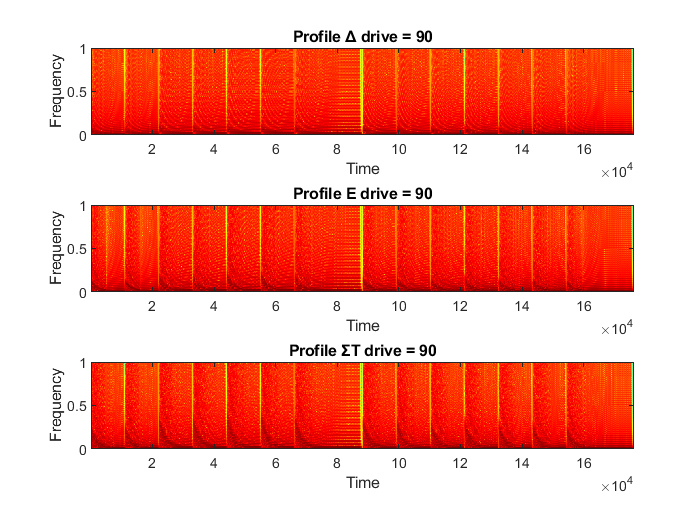

figure
subplot(3,1,1)
specgram(song7_dist2);
title('Profile Δ drive = 90');
subplot(3,1,2)
specgram(song8_dist2);
title('Profile Ε drive = 90');
subplot(3,1,3)
specgram(song9_dist2);
title('Profile ΣΤ drive = 90');

Όταν ο παράγοντας που επηρεάζει την παραμόρφωση (drive) αυξάνεται, αυξάνεται και η περιεκτικότητα του κόκκινου και του πορτοκαλί στα φασματογραφήματα, λόγω της εντονότερης παρουσίας του εφέ (η ένταση όλων των συχνοτήτων αυξάνεται). Ειδικά, στα τρία τελευταία διαγράμματα με το συνδιασμό fm σύνθεσης και παραμόρφωσης είναι πρόδηλη η ένταση όλων των συχνοτήτων (όλο το γράφημα είναι κόκκινο σχεδόν).